# **Data Preprocessing**

Copyright 2018 The MathWorks, Inc.

In this file, we are going to perform data preprocessing, including, data cleaning, data factor creation, data reformatting, and data partitioning.

clear;
close all;
clc;
load data1.mat

## Data cleaning

There are many ways to clean data, for examples, [fill missing values](https://www.mathworks.com/help/matlab/ref/fillmissing.html), [remove missing values](https://www.mathworks.com/help/matlab/ref/rmmissing.html), and [resample data into different time frequency](https://www.mathworks.com/help/matlab/ref/retime.html). 

T = rmmissing(T);

## Factor creation

**Create datetime factors**

Separate datetime into day, month, year.

[T.y,T.m,T.d] = ymd(T.time);

Create day of the week where day 1 of the week is Sunday.

T.dayOfWeek = day(T.time,'dayofweek');

Number of days to next trading day and number of day from previous trading day.

dayDiff = diff(datenum(T.time));
T.nNextTD = [dayDiff; NaN];
T.nPreviousTD = [NaN; dayDiff];

**Generate price related indicators as predictors**

We do not advocate for any technical indicators. Factors below are just examples of how you could incorpoate these indicators into mahcine/deep learning models. More information about functions for creating technical indicatiors can be found [here](https://www.mathworks.com/help/finance/introduction-4.html).

Generate n-day returns

nDay1 = [1, 5, 10, 20];
for i = 1:numel(nDay1)
    factorName = ['ret' num2str(nDay1(i))];
    T.(factorName) = nDayReturn(T.prices, nDay1(i));
end

Generate n-day RSI

nDay2 = [7, 14, 21];
for i = 1:numel(nDay2)
    factorName = ['rsi' num2str(nDay2(i))];
    T.(factorName) = rsindex(T.prices,nDay2(i));
end

Generate MACD

T.MACD = macd(T.prices);

**Generate response variable (Y)**

Use next day returns to generate "Buy (1)" if returns > 0 and "Sell (0)" if returns <= 0. 

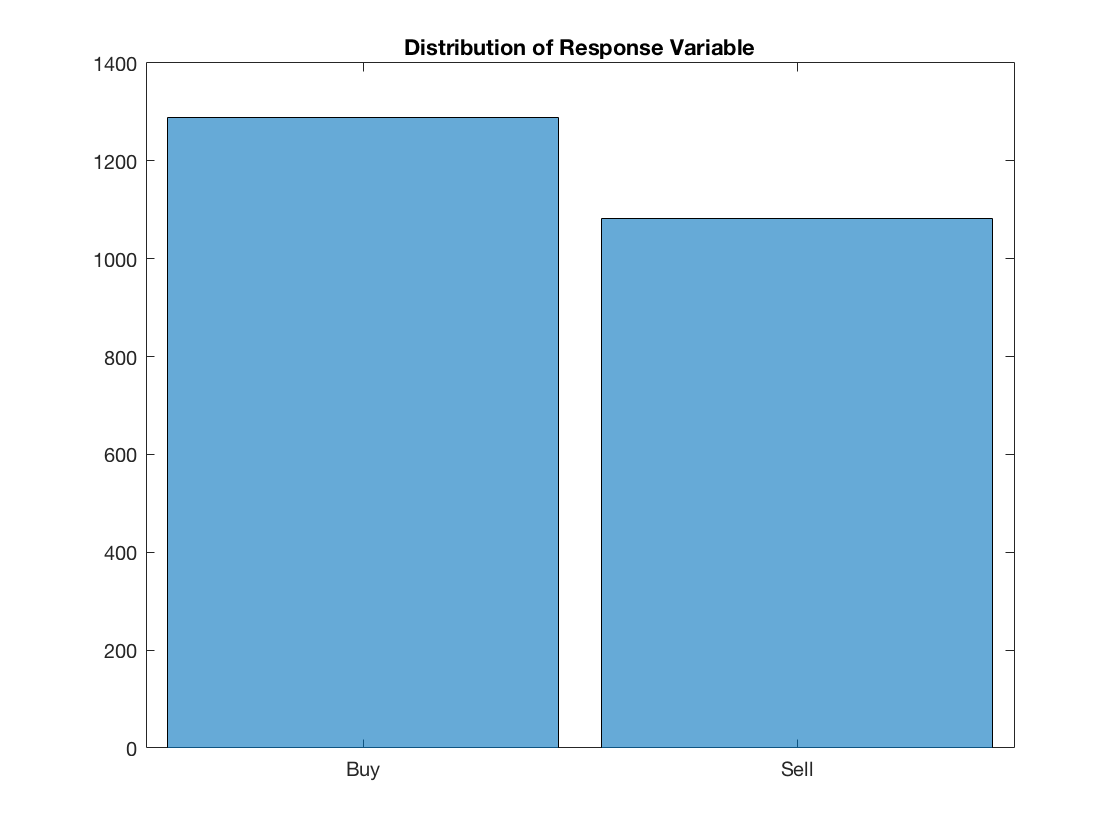

nextDayReturn = double(T.ret1(2:end) > 0);
response = categorical(nextDayReturn,[1,0],{'Buy', 'Sell'});
T.response = [response; missing];
histogram(response,{'Buy','Sell'});
title('Distribution of Response Variable');

clearvars -except T

## Split data into x (predictors) and y (response)

T = rmmissing(T);
T = timetable2table(T);
T.time = []; % Remove time
T.prices = []; % Remove prices
x = T{:,1:end-1};
y = T{:,end};
save('data2.mat')

## Supporting functions

function returns = nDayReturn(prices, nDay)
% This function is to generate nDay return give the price vector
returns = NaN(size(prices,1),1);
returns(nDay+1:end) = prices(nDay+1:end) ./ prices(1:end-nDay) - 1;
end

function rsi = nDayRSI(prices, nDay)
% This function is to generate nDay RSI give the price vector
returns = rsindex(prices,nDay);
returns(nDay+1:end) = prices(nDay+1:end) ./ prices(1:end-nDay) - 1;
end